%Robust control SC42145
%Kinge Keulen (5067162)
%Hannah Gielen ()
addpath('/Users/kingekeulen/Documents/GitHub/Robust-Control-2024');
clear
close

load('Assignment_Data_SC42145.mat')

% Transfer function of the open loop system
G = tf(FWT);

G_11 = -1*G(1,1); % From Beta to Omega x -1
disp(G_11)

  tf with properties:

       Numerator: {[0 0.0799 0.0033 0.8677 -0.0065 0.0346]}
     Denominator: {[1 0.5979 10.9759 4.7093 0.5421 0.1827]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {'Beta (deg)'}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



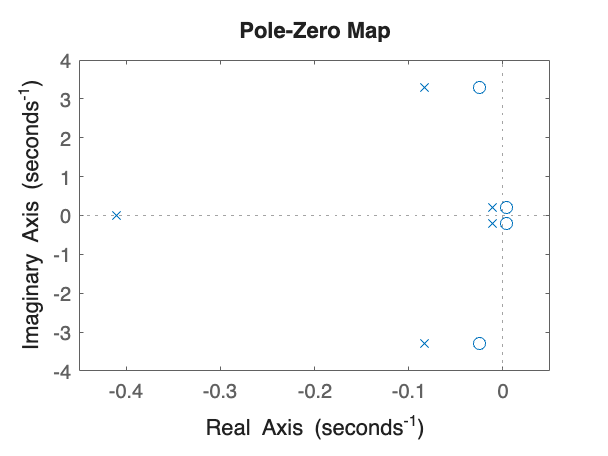

%% Question 1

figure('Name','Figure 1.1','NumberTitle','off')
pzmap(G_11) % pole-zero map of the SISO transfer function

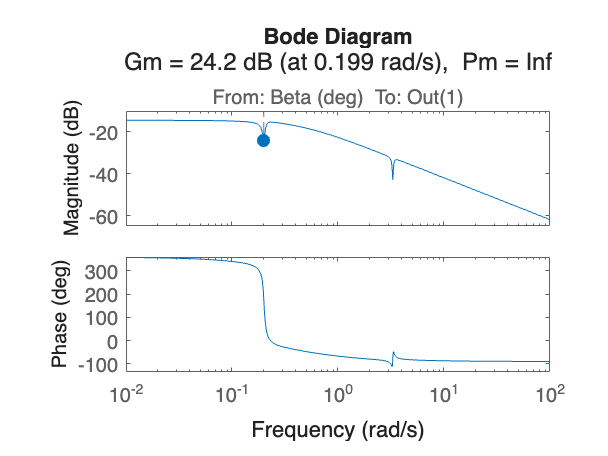


figure('Name','Figure 1.2','NumberTitle','off')
margin(G_11) % bode plot of the SISO transfer function